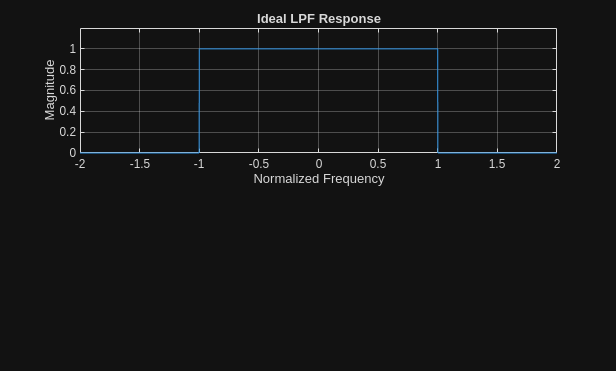

% Define the frequency axis
x4 = -2:0.001:2;

% Define the ideal LPF response
y3 = 0.*(x4 < -1) + 1.*(x4 >= -1 & x4 <= 1) + 0.*(x4 > 1);

% Plot the frequency response
figure;
subplot(2, 1, 1);
plot(x4, y3);
ylim([0 1.2]);
grid on;
ylabel('Magnitude');
xlabel('Normalized Frequency');
title('Ideal LPF Response');


% Compute the IFFT
N = length(y3); % Number of points

Array indices must be positive integers or logical values.

length appears to be both a function and a variable. If this is unintentional, use 'clear length' to remove the variable 'length' from the workspace.

y3_shifted = ifftshift(y3); % Shift zero frequency to the center
time_domain_signal = ifft(y3_shifted); % Compute IFFT
time_domain_signal = fftshift(time_domain_signal); % Shift back for symmetry

% Define the time axis
Fs = 1 / (x4(2) - x4(1)); % Sampling frequency
t = (-N/2:N/2-1) * (1/Fs); % Time axis

% Plot the time-domain signal
subplot(2, 1, 2);
plot(t, real(time_domain_signal)); % Plot the real part
grid on;
ylabel('Amplitude');
xlabel('Time');
title('IFFT of Ideal LPF Response');
xlim([-0.5,0.5]); % Limit the time axis for better visualization

fs = 44.1e3;
fc = 1.2e3;
q = sqrt(2)/2;
q2 = 2;
Q = 1;
[B,A] = BiQuadLPF(fc,fs,q);
[B1,A1] = BiQuadLPF(fc,fs,q2);
[b,a] = BiQuadLPF(fc,fs,Q);
[b2, a2] = BilinearLPF(fc,fs, 10);

[h1,w1] = freqz(B,A,2048,fs);
[h2,w2] = freqz(b,a,2048,fs);
[h3,w3] = freqz(B1,A1,2048,fs);
[h4,w4] = freqz(b2,a2,2048,fs);

f2 = w1*fs / (2*pi);
H1 = 20*log10(abs(h1));
H2 = 20*log10(abs(h2));
H3 = 20*log10(abs(h3));
H4 = 20*log10(abs(h4));

figure;
plot(w1,H1,w2,H2,w3,H3,w4,H4);
legend('Q = 0.707','Q = 1','Q = 2','Order = 10')
grid on
ylim([-70 10])
xlim([0 20e3]);

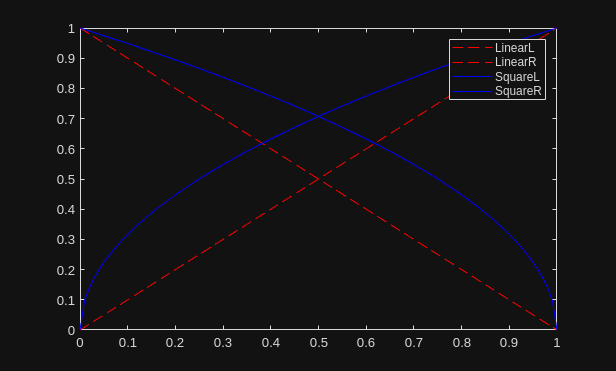

pn = 0:0.01:1;
linL = 1-pn;
linR = pn;
sqrL = sqrt(1-pn);
sqrR = sqrt(pn);



plot(pn,linL,'r--',pn,linR, 'r--',pn,sqrL,'b-',pn,sqrR,'b-');
legend('LinearL','LinearR','SquareL','SquareR');

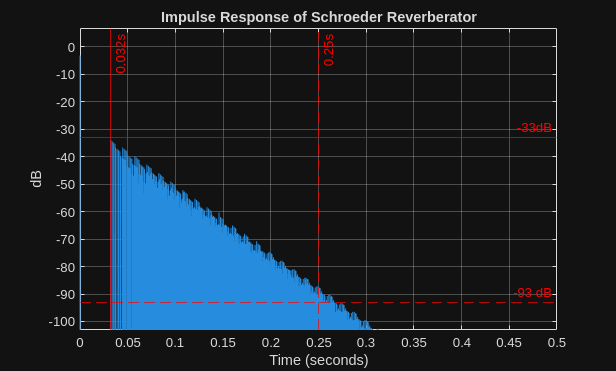

clearvars
fs = 44.1e3;
duration = 10;
impos = 1;

impulse = zeros(1,fs*duration);
impulse(1) = 1;
impulse = impulse';
audiowrite('impulse.wav',impulse,fs);
[y, out1,out2] = schroederReverb(impulse,fs,0.2);
y = y(:,1);
time = linspace(0,10,441000);
time = time';
% Convert to dB
% Add small value to avoid log(0)
eps = 1e-10;
y_db = 20*log10(abs(y) + eps);

% Plot
figure;
plot(time, y_db);
xlabel('Time (seconds)');
ylabel('dB');
title('Impulse Response of Schroeder Reverberator');
grid on;

% Optional: Set y-axis limits to focus on relevant range
% Find the maximum value
max_db = max(y_db);
ylim([max_db-100, max_db+10]);  % Show from max to -80dB below max
xlim([0,0.5])
% Add a line at -60 dB to visualize RT60
yline(max_db-30, 'r-', '-33dB');
yline(max_db-90, 'r--', '-93 dB');
xline(0.032, 'r-', '0.032s');
xline(0.25, 'r--', '0.25s');